# Thermoeconomic Input-Output Analysis

#### Adjacency Matrix Data Model

s=6;t=7;
from=[6 1 1 3 4 5 2 4];
to=  [1 2 3 4 5 3 7 7];
weight=[100 45 30 30 5 4 35 20];

#### Show Graph

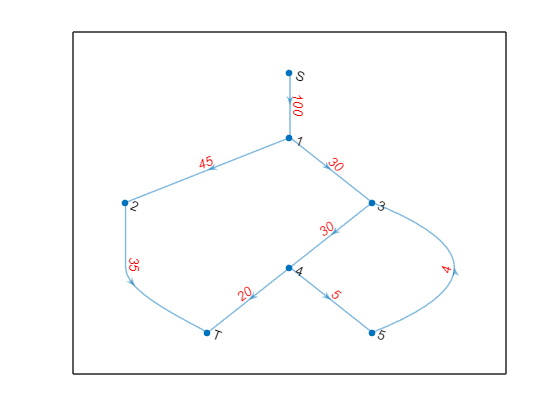

names = {'1','2','3','4','5','S','T'};
dg = digraph(from,to,weight);
plot(dg,'Layout','layered','NodeLabel',names,'EdgeLabel',dg.Edges.Weight,'EdgeLabelColor','red');

#### Test if is the Graph is Productive

M=dg.numnodes;
E = sparse(from,to,weight,M,M);
D = transitiveClosure(E);
sol = mat2str(all(D(s,:)) & all(D(:,t)));
fprintf('Productive graph: %s', sol)

Productive graph: true

#### Build Input-Output Table

N=M-2;
mE = full(E(1:N,1:N));
v0 = full(E(s,1:N));
w0 = full(E(1:N,t));
x = sum(mE,2)+w0;
y = sum(mE,1)+v0;
tfp = [mE,w0,x;v0,0,0;y,0,0];
fdisplay(tfp,'%8.1f','Input Output Table')

Input Output Table
     0.0    45.0    30.0     0.0     0.0     0.0    75.0
     0.0     0.0     0.0     0.0     0.0    35.0    35.0
     0.0     0.0     0.0    30.0     0.0     0.0    30.0
     0.0     0.0     0.0     0.0     5.0    20.0    25.0
     0.0     0.0     4.0     0.0     0.0     0.0     4.0
   100.0     0.0     0.0     0.0     0.0     0.0     0.0
   100.0    45.0    34.0    30.0     5.0     0.0     0.0



#### Calculate Leontief Operator

    A = divideCol(mE,x);
    fdisplay(A,'%10.4f','Technical coeficient matrix')

Technical coeficient matrix
    0.0000    1.2857    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.2000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.2500
    0.0000    0.0000    0.1333    0.0000    0.0000



    L=eye(N)/(eye(N)-A);
    fdisplay(L,'%10.4f','Leontief Operator');

Leontief Operator
    1.0000    1.2857    1.2500    1.5000    1.8750
    0.0000    1.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    1.2500    1.5000    1.8750
    0.0000    0.0000    0.2083    1.2500    1.5625
    0.0000    0.0000    0.1667    0.2000    1.2500



c0=v0./x';
c=[c0*L,1,sum(v0)/sum(w0)];
fdisplay(c,'%10.4f','Process Unit Cost');

Process Unit Cost
    1.3333    1.7143    1.6667    2.0000    2.5000    1.0000    1.8182



#### Calculate Distribution Cost operator

B=divideRow(mE,x);
fdisplay(full(B),'%10.4f','Distribution Matrix')

Distribution Matrix
    0.0000    0.6000    0.4000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.2000
    0.0000    0.0000    1.0000    0.0000    0.0000



fprintf('Spectral Ratio: %10.4f',abs(eigs(A,1)));

Spectral Ratio:     0.5848

G=eye(N)/(eye(N)-B);
fdisplay(G,'%10.4f','Distribution Cost Operator');

Distribution Cost Operator
    1.0000    0.6000    0.5000    0.5000    0.1000
    0.0000    1.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    1.2500    1.2500    0.2500
    0.0000    0.0000    0.2500    1.2500    0.2500
    0.0000    0.0000    1.2500    1.2500    1.2500



#### Show Cost Graph

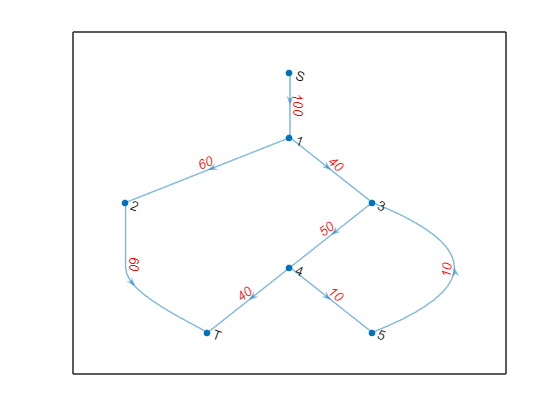

cost = weight .* c(from);
dg = digraph(from,to,cost);
plot(dg,'Layout','layered','NodeLabel',names,'EdgeLabel',dg.Edges.Weight,'EdgeLabelColor','red');